addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_standard\20240105_02\
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layer\20240105_02\

load Data_img_01_20240105_02_005.mat
load Data_20240105_02_005.mat


power = calibrateBrightness(20240105, 02, 005);

outputBrightness = 1.0e-10 *

    0.0003    0.0003    0.0003    0.0002    0.0002    0.0003    0.0003    0.0004    0.0008    0.0005    0.0007    0.0006    0.0003    0.0002    0.0002    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0003    0.0001    0.0000    0.0000    0.0001


depth = twtt2Depth(twtt, 1.77); % rwo 1 = surface, row 2 = bottom variables

depth = 1.0e+03 *

    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3424    0.3429    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430
    2.6344    2.6347    2.6333    2.6301    2.6275    2.6270    2.6274    2.6282    2.6286    2.6287    2.6293    2.6303    2.6319    2.6336    2.6347    2.6353    2.6355    2.6347    2.6330    2.6301    2.6265    2.6247    2.6237    2.6221    2.6200    2.6174    2.6147    2.6119    2.6095    2.6076    2.6063    2.6053    2.6056    2.6067    2.6098    2.6138    2.6191    2.6226    2.6225    2.6216    2.6207    2.6197    2.6188    2.6159    2.6124    2.6102    2.6087    2.6084

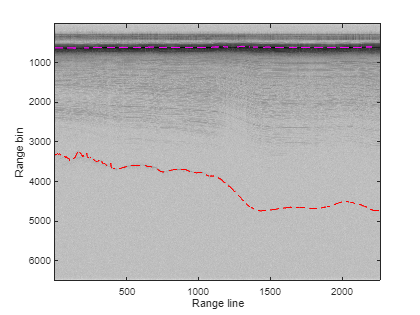

close all

echo = load('Data_img_01_20240105_02_005.mat','Data','Time','GPS_time');
h_fig = figure;
h_axes = axes;
imagesc(lp(echo.Data),'parent',h_axes);
colormap(h_axes,1-gray(256));
xlabel('Range line','parent',h_axes);
ylabel('Range bin','parent',h_axes);


layer = load('C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layerData\20240105_02\Data_20240105_02_005.mat','GPS_time','layerData');
Surface = interp1(echo.Time,1:length(echo.Time),layer.layerData{1}.value{2}.data);
Bottom = interp1(echo.Time,1:length(echo.Time),layer.layerData{2}.value{2}.data);
Surface = interp1(layer.GPS_time,Surface,echo.GPS_time);
Bottom = interp1(layer.GPS_time,Bottom,echo.GPS_time);

hold(h_axes,'on');
plot(Surface,'m--','parent',h_axes);
plot(Bottom,'r--','parent',h_axes);
hold off

a = 1:length(Bottom);
newLength = size(depth, 2);
ai = linspace(1, length(a), newLength);
interpBottom = interp1(a, Bottom, ai, 'cubic')

interpBottom = 1.0e+03 *

    3.3294    3.3277    3.3249    3.3219    3.3213    3.3216    3.3223    3.3228    3.3232    3.3239    3.3251    3.3270    3.3290    3.3300    3.3306    3.3305    3.3295    3.3277    3.3249    3.3210    3.3189    3.3173    3.3158    3.3138    3.3111    3.3080    3.3049    3.3020    3.2995    3.2975    3.2960    3.2953    3.2961    3.2990    3.3035    3.3084    3.3127    3.3154    3.3152    3.3144    3.3133    3.3122    3.3102    3.3071    3.3031    3.3005    3.2992    3.2993    3.2997    3.3004


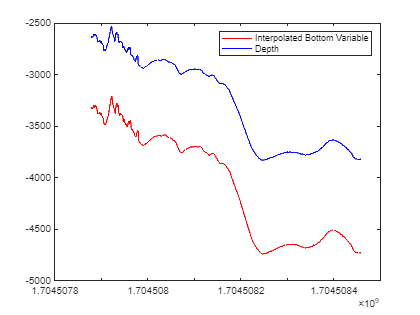

depth(2, :);

plot(gps_time, -interpBottom, 'r')
hold on 
plot(gps_time, -depth(2, :), 'b')
legend('Interpolated Bottom Variable', 'Depth ')
hold off

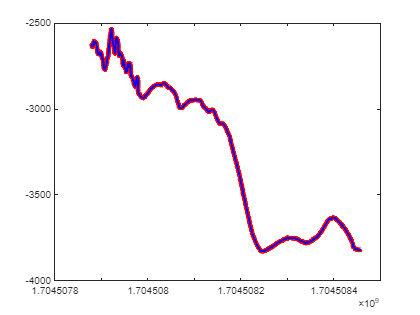

shiftedAmount = depth(2,:) - interpBottom; % amount to shift bottom to be equal to depth variable!

plot(gps_time, -interpBottom-shiftedAmount, 'r','LineWidth', 5)
hold on 
plot(gps_time, -depth(2, :), 'b','LineWidth', 2)
hold off

Bin = round(Bottom);

plot(GPS_time, -Bin, 'r', 'LineWidth', 3)

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

hold on 
plot(GPS_time, -Bottom, 'g')


% NEXT : compare twtt and range bin (they should be different?)